data

clear all
clc
close all

S=0.0002;           %slope
M=100*10^9;         %microg uranium
Clim=15;            %limit of concentration [microg/L]
xO=47000;           %position of omaha [m]
xP=73000;           %position of Plattsmouth [m]
xN=132000;          %position of nebraska city [m]
ro=1000;            %water density [kg/m^3]
            

# HYDRAULIC PROPERTIES

%Low Flows
Amavg=1747;         %area of the cross section Missouri monte [m^2]
Amlow=198;   
wmavg=316;          %width [m]
wmlow=157;
hmlow=2.52;          
pmlow=157;        
Rimlow=Amlow/pmlow; %hydraulic radius
Ustarmlow=sqrt(9.81*3600*Rimlow*S);
Qmlow=92*60;          %discharge (taken from hydrology part) m^3/min
Umlow=Qmlow/Amlow;  %bulk velocity of the river [m/min]
             %dispersion coefficient [m^2/min]
Kmlow(1)=0.011*((wmlow^2*Umlow^2)/(hmlow*Ustarmlow)); 
Kmlow(2)=0.058*(hmlow*Umlow)/S;
Kmlow(3)=0.18*((Ustarmlow/Umlow)^1.5)*(wmlow^2*Umlow^2)/(hmlow*Ustarmlow);
Kmlow(4)=5.915*hmlow*Ustarmlow*(wmlow/hmlow)^0.62*(Umlow/Ustarmlow)^1.428;
Kmlow(5)=2*hmlow*Ustarmlow*(wmlow/hmlow)^1.5;
Kmlow(6)=10.612*hmlow*Umlow*(Umlow/Ustarmlow);
Kmlow(7)=2*hmlow*Ustarmlow*(wmlow/hmlow)^0.96*(Umlow/Ustarmlow);
Kmmin_low = min(Kmlow);
Kmmax_low = max(Kmlow);

%Average
Amavg=1747;         %area of the cross section Missouri monte [m^2]  
wmavg=316;          %width [m]
hmavg=9.31;          
pmavg=316.4;        
Rimavg=Amavg/pmavg; %hydraulic radius
Ustarmavg=sqrt(9.81*3600*Rimavg*S);
Qmavg=633*60;          %discharge (taken from hydrology part)
Umavg=Qmavg/Amavg;  %bulk velocity of the river [m/min]
             %dispersion coefficient [m^2/min]
Kmavg(1)=0.011*((wmavg^2*Umavg^2)/(hmavg*Ustarmavg)); % Fischer
Kmavg(2)=0.058*(hmavg*Umavg)/S; % Mcquivery & Keefer
Kmavg(3)=0.18*((Ustarmavg/Umavg)^1.5)*(wmavg^2*Umavg^2)/(hmavg*Ustarmavg); % Liu
Kmavg(4)=5.915*hmavg*Ustarmavg*(wmavg/hmavg)^0.62*(Umavg/Ustarmavg)^1.428; % Seo & Chong
Kmavg(5)=2*hmavg*Ustarmavg*(wmavg/hmavg)^1.5; % Iwasa & Aya
Kmavg(6)=10.612*hmavg*Umavg*(Umavg/Ustarmavg); % Kashefipour & Falconer
Kmavg(7)=2*hmavg*Ustarmavg*(wmavg/hmavg)^0.96*(Umavg/Ustarmavg); % Saway & Dutta
Kmmin_avg = min(Kmavg);
Kmmax_avg = max(Kmavg);

 AFTER THE JUNCTION

Ajavg=2100;         %area of the cross section after the junction
Ajlow=375;   
wjavg=335;          %width after the junction
wjlow=166;
Qjlow=(15+92)*60;
hjlow=3.62;          
pjlow=166;        
Rijlow=Ajlow/pjlow; %hydraulic radius
Ustarjlow=sqrt(9.81*3600*Rijlow*S);
Ujlow=(Qjlow)/Ajlow;  %bulk velocity of the river [m/min]
             %dispersion coefficient [m^2/min]
Kjlow(1)=0.011*((wjlow^2*Ujlow^2)/(hjlow*Ustarjlow)); 
Kjlow(2)=0.058*(hjlow*Ujlow)/S;
Kjlow(3)=0.18*((Ustarjlow/Ujlow)^1.5)*(wjlow^2*Ujlow^2)/(hjlow*Ustarjlow);
Kjlow(4)=5.915*hjlow*Ustarjlow*(wjlow/hjlow)^0.62*(Ujlow/Ustarjlow)^1.428;
Kjlow(5)=2*hjlow*Ustarjlow*(wjlow/hjlow)^1.5;
Kjlow(6)=10.612*hjlow*Ujlow*(Ujlow/Ustarjlow);
Kjlow(7)=2*hjlow*Ustarjlow*(wjlow/hjlow)^0.96*(Ujlow/Ustarjlow);
Kjmin_low = min(Kjlow);
Kjmax_low = max(Kjlow);

%Average
Ajavg=2100;         %area of the cross section after the junction
wjavg=335;          %width after the junction
hjavg=10.4;
pjavg=335.6;        
Rijavg=Ajavg/pjavg; %hydraulic radius
Ustarjavg=sqrt(9.81*3600*Rijavg*S);
Qjavg=(633+240)*60;          %discharge (taken from hydrology part)
Ujavg=Qjavg/Ajavg;  %bulk velocity of the river [m/min]



Kjavg(1)=0.011*((wjavg^2*Ujavg^2)/(hjavg*Ustarjavg)); % Fischer
Kjavg(2)=0.058*(hjavg*Ujavg)/S; % Mcquivery & Keefer
Kjavg(3)=0.18*((Ustarjavg/Ujavg)^1.5)*(wjavg^2*Ujavg^2)/(hjavg*Ustarjavg); % Liu
Kjavg(4)=5.915*hjavg*Ustarjavg*(wjavg/hjavg)^0.62*(Ujavg/Ustarjavg)^1.428; % Seo & Chong
Kjavg(5)=2*hjavg*Ustarjavg*(wjavg/hjavg)^1.5; % Iwasa & Aya
Kjavg(6)=10.612*hjavg*Ujavg*(Ujavg/Ustarjavg); % Kashefipour & Falconer
Kjavg(7)=2*hjavg*Ustarjavg*(wjavg/hjavg)^0.96*(Ujavg/Ustarjavg); % Saway & Dutta
Kjmin_avg = min(Kjavg);
Kjmax_avg = max(Kjavg);

# OMAHA

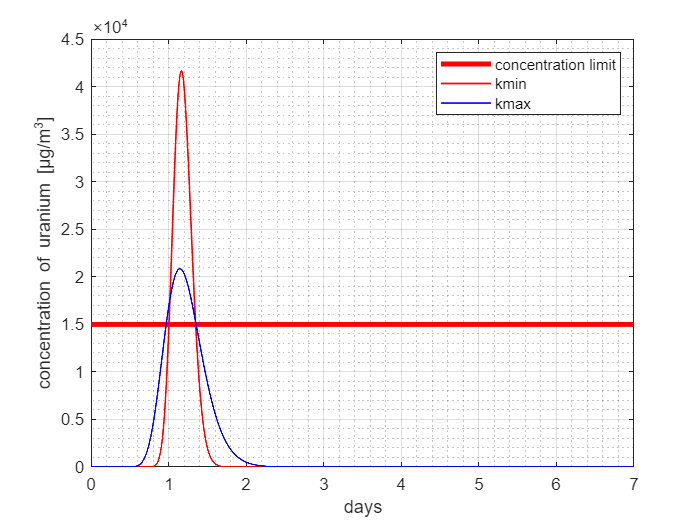

t=[1:10080];     %7 days

C_Omaha_low1=M./(Amlow*sqrt(4*pi*Kmmin_low*t)).*exp(-((xO-Umlow*t).^2)./(4*Kmmin_low*t));
C_Omaha_low2=M./(Amlow*sqrt(4*pi*Kmmax_low*t)).*exp(-((xO-Umlow*t).^2)./(4*Kmmax_low*t));
Clim_graph=Clim*ones(length(t),1)*1000;
figure(1)

plot(t/(24*60),Clim_graph,'r','LineWidth',3);hold on
plot(t/(24*60),C_Omaha_low1, 'r','LineWidth',1);hold on
plot(t/(24*60),C_Omaha_low2, 'b','LineWidth',1);hold off
xlabel('days')
ylabel('concentration of uranium [\mug/m^3]')
legend('concentration limit','kmin','kmax')
grid on 
grid minor

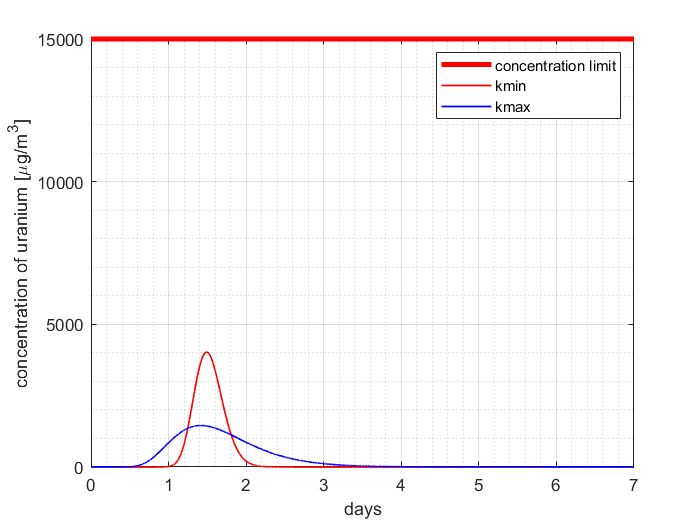

C_Omaha_avg1=M./(Amavg*sqrt(4*pi*Kmmin_avg*t)).*exp(-((xO-Umavg*t).^2)./(4*Kmmin_avg*t));
C_Omaha_avg2=M./(Amavg*sqrt(4*pi*Kmmax_avg*t)).*exp(-((xO-Umavg*t).^2)./(4*Kmmax_avg*t));

Clim_graph=Clim*ones(length(t),1)*1000;
figure(2)

plot(t/(24*60),Clim_graph,'r','LineWidth',3);hold on
plot(t/(24*60),C_Omaha_avg1, 'r','LineWidth',1);hold on
plot(t/(24*60),C_Omaha_avg2, 'b','LineWidth',1);hold off
xlabel('days')
ylabel('concentration of uranium [\mug/m^3]')
legend('concentration limit','kmin','kmax')
grid on 
grid minor

# PLATTSMOUTH BEFORE THE JUNCTION

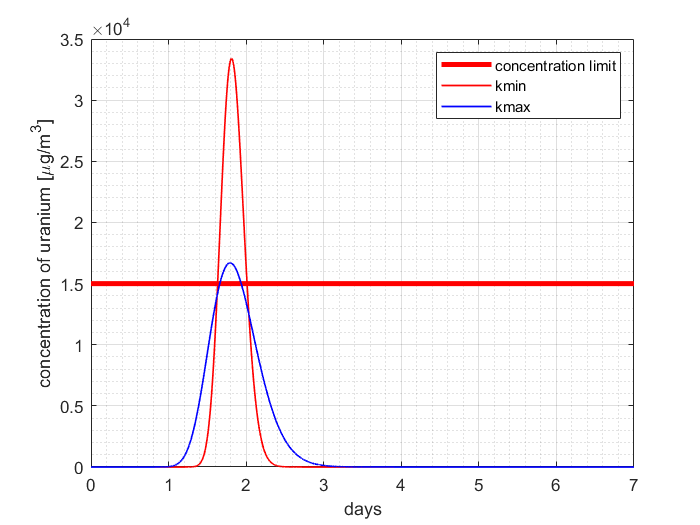

C_plattb4_low1=M./(Amlow*sqrt(4*pi*Kmmin_low*t)).*exp(-((xP-Umlow*t).^2)./(4*Kmmin_low*t));
C_plattb4_low2=M./(Amlow*sqrt(4*pi*Kmmax_low*t)).*exp(-((xP-Umlow*t).^2)./(4*Kmmax_low*t));
Clim_graph=Clim*ones(length(t),1)*1000;
figure(3)

plot(t/(24*60),Clim_graph,'r','LineWidth',3);hold on
plot(t/(24*60),C_plattb4_low1, 'r','LineWidth',1);hold on
plot(t/(24*60),C_plattb4_low2, 'b','LineWidth',1);hold off
ylabel('concentration of uranium [\mug/m^3]')
xlabel('days')
legend('concentration limit','kmin','kmax')
grid on 
grid minor

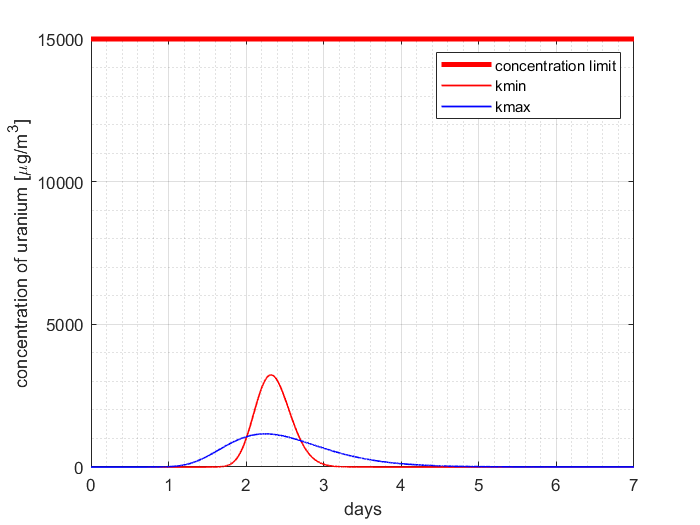

C_plattb4_avg1=M./(Amavg*sqrt(4*pi*Kmmin_avg*t)).*exp(-((xP-Umavg*t).^2)./(4*Kmmin_avg*t));
C_plattb4_avg2=M./(Amavg*sqrt(4*pi*Kmmax_avg*t)).*exp(-((xP-Umavg*t).^2)./(4*Kmmax_avg*t));

Clim_graph=Clim*ones(length(t),1)*1000;
figure(4)

plot(t/(24*60),Clim_graph,'r','LineWidth',3);hold on
plot(t/(24*60),C_plattb4_avg1, 'r','LineWidth',1);hold on
plot(t/(24*60),C_plattb4_avg2, 'b','LineWidth',1);hold off
ylabel('concentration of uranium [\mug/m^3]')
xlabel('days')
legend('concentration limit','kmin','kmax')
grid on 
grid minor

# PLATTSMOUTH AFTER THE JUNCTION

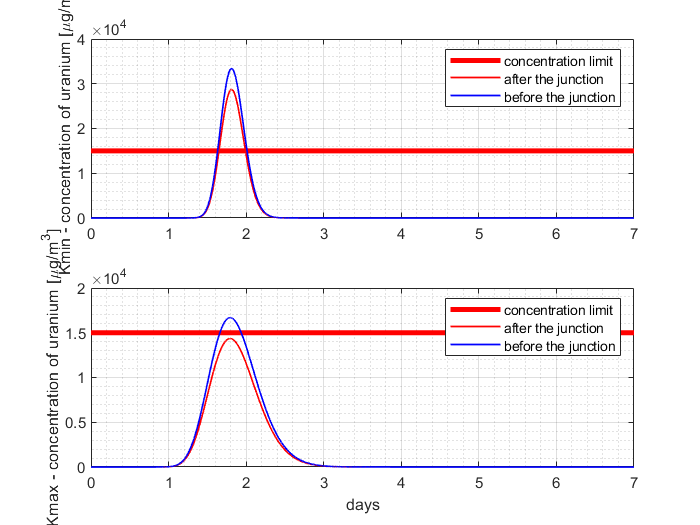

C_plattAft_lowkmin=(Qmlow/(Qjlow))*C_plattb4_low1;
C_plattAft_lowkmax=(Qmlow/(Qjlow))*C_plattb4_low2;
figure(5)
title('concentration of uranium at Plattsmouth')
subplot(2,1,1)
plot(t/(24*60),Clim_graph,'r','LineWidth',3);hold on
plot(t/(24*60),C_plattAft_lowkmin,'r','LineWidth',1); hold on
plot(t/(24*60),C_plattb4_low1,'b','LineWidth',1);
ylabel('Kmin - concentration of uranium [\mug/m^3]')
legend('concentration limit', 'after the junction','before the junction')
grid on
grid minor
subplot(2,1,2)
plot(t/(24*60),Clim_graph,'r','LineWidth',3);hold on
plot(t/(24*60),C_plattAft_lowkmax,'r','LineWidth',1); hold on
plot(t/(24*60),C_plattb4_low2,'b','LineWidth',1);
ylabel('Kmax - concentration of uranium [\mug/m^3]')
xlabel('days')
legend('concentration limit', 'after the junction','before the junction')
grid on
grid minor

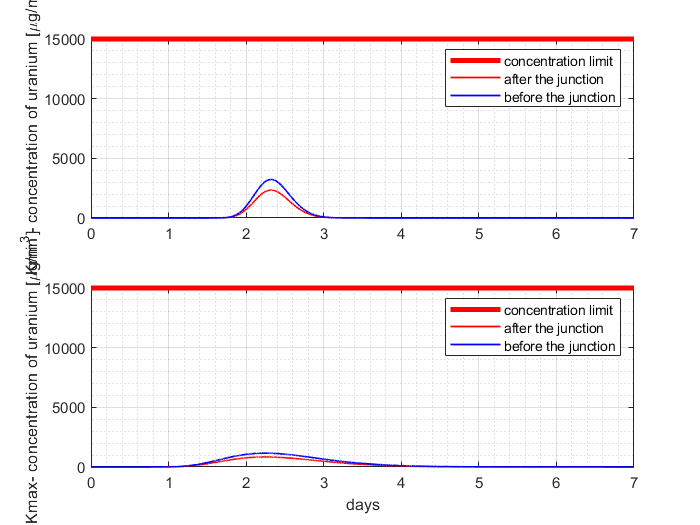

C_plattAft_avgkmin=(Qmavg/(Qjavg))*C_plattb4_avg1;
C_plattAft_avgkmax=(Qmavg/(Qjavg))*C_plattb4_avg2;
figure(6)
title('concentration of uranium at Plattsmouth')
subplot(2,1,1)
plot(t/(24*60),Clim_graph,'r','LineWidth',3);hold on
plot(t/(24*60),C_plattAft_avgkmin,'r','LineWidth',1); hold on
plot(t/(24*60),C_plattb4_avg1,'b','LineWidth',1);
ylabel('Kmin - concentration of uranium [\mug/m^3]')
legend('concentration limit', 'after the junction','before the junction')
grid on
grid minor
subplot(2,1,2)
plot(t/(24*60),Clim_graph,'r','LineWidth',3);hold on
plot(t/(24*60),C_plattAft_avgkmax,'r','LineWidth',1); hold on
plot(t/(24*60),C_plattb4_avg2,'b','LineWidth',1);
ylabel('Kmax- concentration of uranium [\mug/m^3]')
xlabel('days')
legend('concentration limit', 'after the junction','before the junction')
grid on
grid minor

# NEBRASKA CITY

M_Final_kmin_low = C_plattAft_lowkmin*Qjlow;
M_Final_kmax_low = C_plattAft_lowkmax*Qjlow;



M_Final_kmin_avg = C_plattAft_avgkmin*Qjavg;
M_Final_kmax_avg = C_plattAft_avgkmax*Qjavg;


C_Neb_kmin_low = zeros(length(t), length(t)+1);
C_Neb_kmax_low = zeros(length(t), length(t)+1);
C_Neb_kmin_avg = zeros(length(t), length(t)+1);
C_Neb_kmax_avg = zeros(length(t), length(t)+1);

C_Neb_Final_kmin_low = zeros(length(t),1);
C_Neb_Final_kmax_low = zeros(length(t),1);
C_Neb_Final_kmin_avg = zeros(length(t),1);
C_Neb_Final_kmax_avg = zeros(length(t),1);


tic
for i=1:length(t)
        for j = i+1:length(t)+1
        C_Neb_kmin_low(i,j) = M_Final_kmin_low(i)/(Ajlow*sqrt(4*pi*Kjmin_low*(j-i)))*exp(-(((xN-xP)-Ujlow*(j-i))^2)/(4*Kjmin_low*(j-i)));
        C_Neb_kmax_low(i,j) = M_Final_kmax_low(i)/(Ajlow*sqrt(4*pi*Kjmax_low*(j-i)))*exp(-(((xN-xP)-Ujlow*(j-i))^2)/(4*Kjmax_low*(j-i)));
        C_Neb_kmin_avg(i,j) = M_Final_kmin_avg(i)/(Ajavg*sqrt(4*pi*Kjmin_avg*(j-i)))*exp(-(((xN-xP)-Ujavg*(j-i))^2)/(4*Kjmin_avg*(j-i)));
        C_Neb_kmax_avg(i,j) = M_Final_kmax_avg(i)/(Ajavg*sqrt(4*pi*Kjmax_avg*(j-i)))*exp(-(((xN-xP)-Ujavg*(j-i))^2)/(4*Kjmax_avg*(j-i)));
        end
end
for i=1:(length(t))
    C_Neb_Final_kmin_low(i) = sum(C_Neb_kmin_low(:,i));
    C_Neb_Final_kmax_low(i) = sum(C_Neb_kmax_low(:,i));
    C_Neb_Final_kmin_avg(i) = sum(C_Neb_kmin_avg(:,i));
    C_Neb_Final_kmax_avg(i) = sum(C_Neb_kmax_avg(:,i));
end
toc

Elapsed time is 4.368040 seconds.


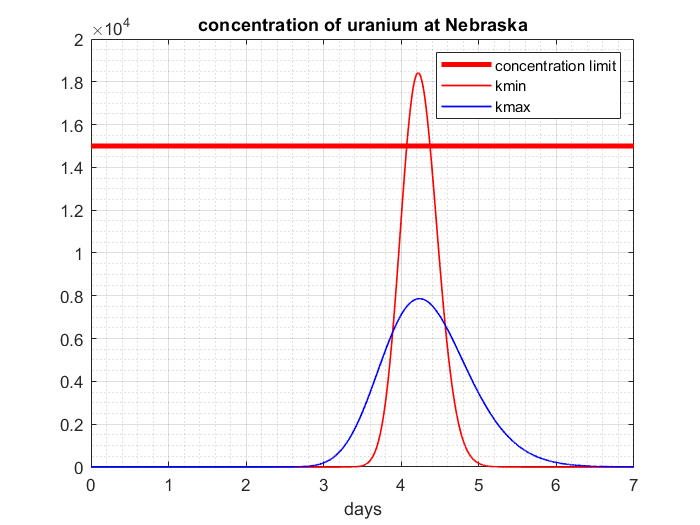

figure(7)
plot(t/(24*60),Clim_graph,'r','LineWidth',3);hold on
plot(t/(24*60),C_Neb_Final_kmin_low, 'r','LineWidth',1);hold on
plot(t/(24*60),C_Neb_Final_kmax_low, 'b','LineWidth',1);hold off
legend('concentration limit','kmin','kmax')
title('concentration of uranium at Nebraska')
xlabel('days')
grid on 
grid minor

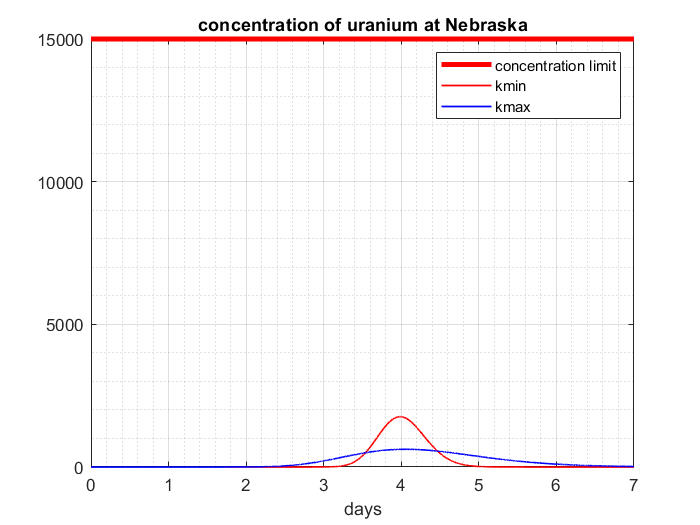

figure(8)
plot(t/(24*60),Clim_graph,'r','LineWidth',3);hold on
plot(t/(24*60),C_Neb_Final_kmin_avg, 'r','LineWidth',1);hold on
plot(t/(24*60),C_Neb_Final_kmax_avg, 'b','LineWidth',1);hold off
legend('concentration limit','kmin','kmax')
title('concentration of uranium at Nebraska')
xlabel('days')
grid on 
grid minor